## Task 1

### Exercicio 1

    Generate a matrix with 3 rows and 10,000 columns of random numbers between 0.0 and 1.0 (i.e., each column represents an experiment):

experiments = rand(3,10000);

    Generate a matrix with 3 rows and 10,000 columns with the value 1 if the value of the previous matrix is less than 0.5 (i.e., if it came up heads) or with the value 0 otherwise (i.e., if it came up tails):

tosses = experiments < 0.5; % 0.5 corresponds to the prob. of heads

    Generate a row vector with 10,000 elements with the sum of the values of each column of the previous matrix (i.e., the number of heads in each experiment):

results = sum(tosses);

    Generate a row vector with 10,000 elements with the value 1 when the value of the previous vector is 2 (i.e., if the experiment gave 2 heads) or 0 when it is different from 2:

successes = results == 2;

    Determine the result by dividing the number of experiments with 2 heads by the total number of experiments:

probSimulation = (sum(successes)/10000)*100

probSimulation = 37.6400

#### Code 1 - second version

N = 1e4; % number of experiments
p = 0.5; % probability of heads
k = 2; % number of heads
n = 3; % number of tosses
tosses = rand(n,N) < p;
results = sum(tosses);
successes = sum(results == k) ;
probSimulation = (successes/N)*100

probSimulation = 37.5200

    A percentagem média é de 37

### Exercicio 2

a)

experiments = rand(15,10000);
tosses = experiments < 0.5;
results = sum(tosses);
successes = results == 6;
prob = (sum(successes)/10000)*100

prob = 15.0200

b)

experiments = rand(15,10000);
tosses = experiments < 0.5;
results = sum(tosses);
successes = results >= 6;
prob = (sum(successes)/10000)*100

prob = 84.8900

### Exercicio 3

function probSim = estimarProbabilidade(p, n, k, N)
    % p: probabilidade de ser cara
    % n: número de lançamentos por experiência
    % k: número de sucessos desejados
    % N: número de experiências (repetições da simulação)

    % Gera matriz de lançamentos (0 ou 1)
    tosses = rand(n, N) < p;

    % Soma os sucessos em cada experiência (soma ao longo das colunas)
    results = sum(tosses);
    
    % Conta sucessos em cada coluna e verifica se é igual a k
    successes = sum(results == k);
    
    % Calcula a frequência relativa
    probSim = (successes / N)*100;
end

% Ex 1: 2 caras em 3 lançamentos
prob_ex1 = estimarProbabilidade(0.5, 3, 2, 10000);

% Ex 2(a): 6 caras em 15 lançamentos
prob_ex2a = estimarProbabilidade(0.5, 15, 6, 10000);

b)

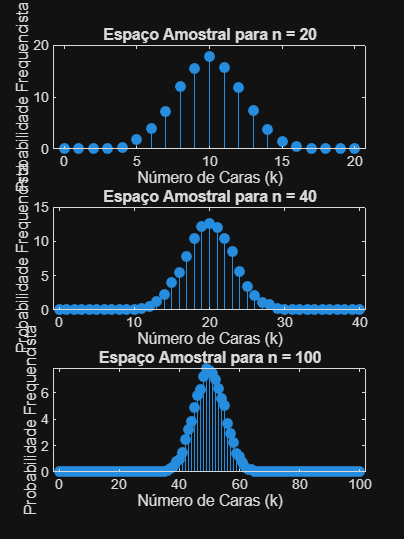

N = 10000; % Número de experiências
p = 0.5;
n_values = [20, 40, 100];

figure('Position', [100, 100, 600, 800]);
for i = 1:length(n_values)
    n = n_values(i);
    probs_espaco_amostral = zeros(1, n + 1);
    
    % Calcula a probabilidade para cada número de caras (k de 0 a n)
    for k = 0:n
        probs_espaco_amostral(k + 1) = estimarProbabilidade(p, n, k, N);
    end
    
    % Plota o gráfico usando subplot para ficarem os 3 na mesma janela
    subplot(3, 1, i);
    stem(0:n, probs_espaco_amostral, 'filled');
    title(['Espaço Amostral para n = ', num2str(n)]);
    xlabel('Número de Caras (k)');
    ylabel('Probabilidade Frequencista');
end

### Exercicio 4